% Script para gerar o Mapa de Polos e Zeros do sistema de posição

clear; clc; close all;

% --- 1. Definição dos Parâmetros do Sistema ---
% Reutilizando os mesmos parâmetros 
Ra = 1.0; La = 0.5; Kt = 0.01; Kb = 0.01;
J_total = 0.06; b_total = 0.12;

% --- 2. Criação da Função de Transferência de Posição P(s) ---
% P(s) = Theta(s)/Va(s) - Equação 15 do documento 
numP = [Kt];
denP = [La*J_total   (Ra*J_total + La*b_total)   (Ra*b_total + Kt*Kb)   0];
P_motor_position = tf(numP, denP);

disp('Polos do sistema de posição:');

Polos do sistema de posição:


pole(P_motor_position)

ans =    0.0000 + 0.0000i
  -2.0000 + 0.0577i
  -2.0000 - 0.0577i


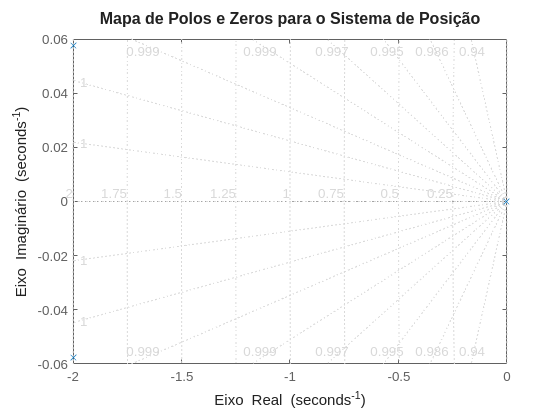


% --- 3. Geração do Mapa de Polos e Zeros ---
figure('Name', 'Mapa de Polos e Zeros');
pzmap(P_motor_position); % Comando para gerar o mapa 
grid on;
title('Mapa de Polos e Zeros para o Sistema de Posição', 'FontSize', 12);

xlabel('Eixo Real');
ylabel('Eixo Imaginário');